plot(YELLOWvoltage,YELLOWcurrent,'.')
hold on,


%%CREATING ERRORBARS
xneg=0.001.*[1 1 1 1 1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-13).*[1 1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(YELLOWvoltage,YELLOWcurrent,yneg,ypos,xneg,xpos,'o')


%%NEGATIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =      -2.000e-13  (-1.667e-12, 1.267e-12)   (\pm 0.367e-12)
  %     p2 =   5.333e-14  (-5.366e-13, 6.433e-13)       (\pm 2.950e-13)

%Goodness of fit:
 % SSE: 6.667e-29
  %R-square: 0.75
 % Adjusted R-square: 0.5
  %RMSE: 8.165e-15
  
  p1 =      -2e-13  

p1 = -2.0000e-13

  p2 =   5.333e-14

p2 = 5.3330e-14

  f = p1*YELLOWvoltage + p2

f = 	1.0e+-13 *

    0.4333    0.3333    0.2333    0.1333    0.0333   -0.0667   -0.1667   -0.2667   -0.3667   -0.4667


  plot(YELLOWvoltage,f,'m')
  
  %%POSITIVE SIDE FIT   
  %Linear model Poly1:
   %  g(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =    -5.2e-13  (-8.181e-13, -2.219e-13)   (\pm 1.490e-13)
  %     p4 =    1.46e-13  (9.124e-14, 2.008e-13)     (\pm 0.274e-13)

%Goodness of fit:
 % SSE: 1.2e-28
  %R-square: 0.9657
  %Adjusted R-square: 0.9486
  %RMSE: 7.746e-15
  
  p3 =    -5.2e-13  

p3 = -5.2000e-13

  p4 =    1.46e-13

p4 = 1.4600e-13

  g = p3*YELLOWvoltage + p4

g = 	1.0e+-12 *

    0.1200    0.0940    0.0680    0.0420    0.0160   -0.0100   -0.0360   -0.0620   -0.0880   -0.1140


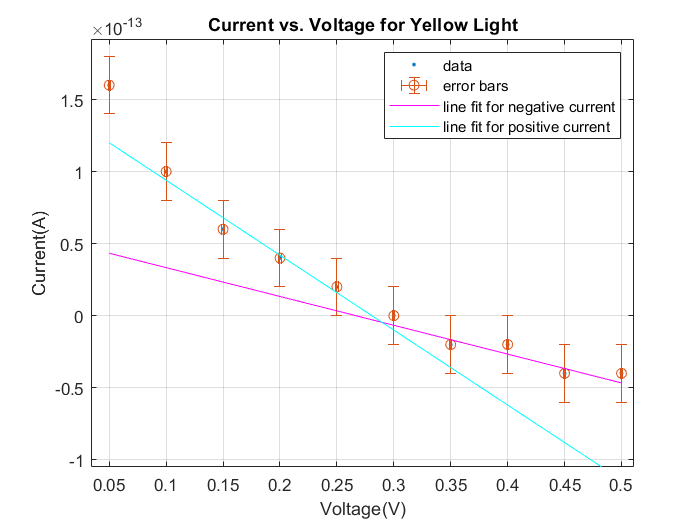

  plot(YELLOWvoltage,g,'c')
  
  grid on
  
  title('Current vs. Voltage for Yellow Light')
xlabel('Voltage(V)')
ylabel('Current(A)')
legend({'data','error bars','line fit for negative current','line fit for positive current'})

xlim([0.034 0.511])
ylim([-0.000000000000105 0.000000000000192])